# scrpits for ppt

close all;clear;clc;
[~, ~, ~, criticalEventTrain] = spikeTime2Train("data/data_rat010_0615_event");
[~, ~, ~, wellTrainedEventTrain] = spikeTime2Train("data/rat_010_07_04.mat");

length(criticalEventTrain)/100

ans = 2.8676e+03

length(wellTrainedEventTrain)/100

ans = 1.4456e+03

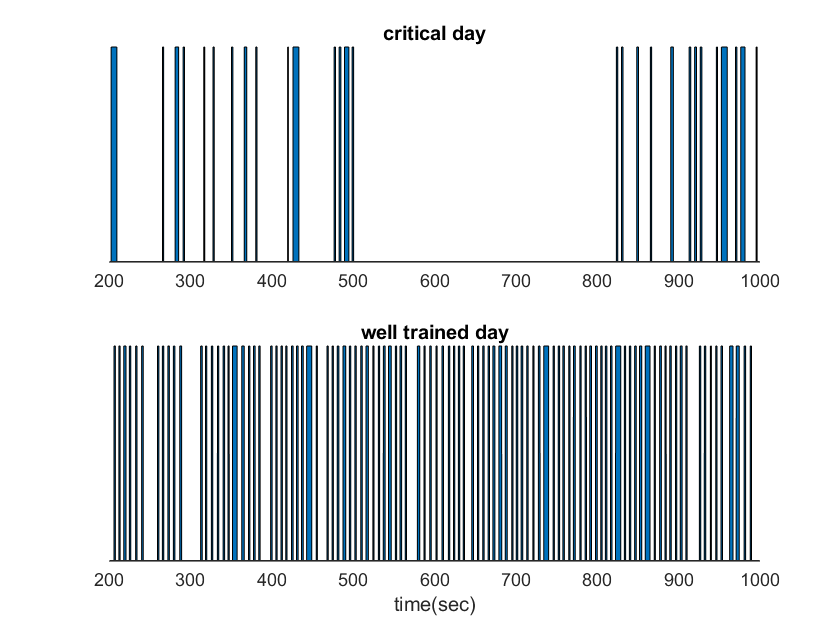


timebins=20000:100000;
t=timebins/100;
figure
subplot(2,1,1)
area(t, criticalEventTrain(timebins))
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
title("critical day")
subplot(2,1,2)
area(t, wellTrainedEventTrain(timebins))
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title("well trained day")

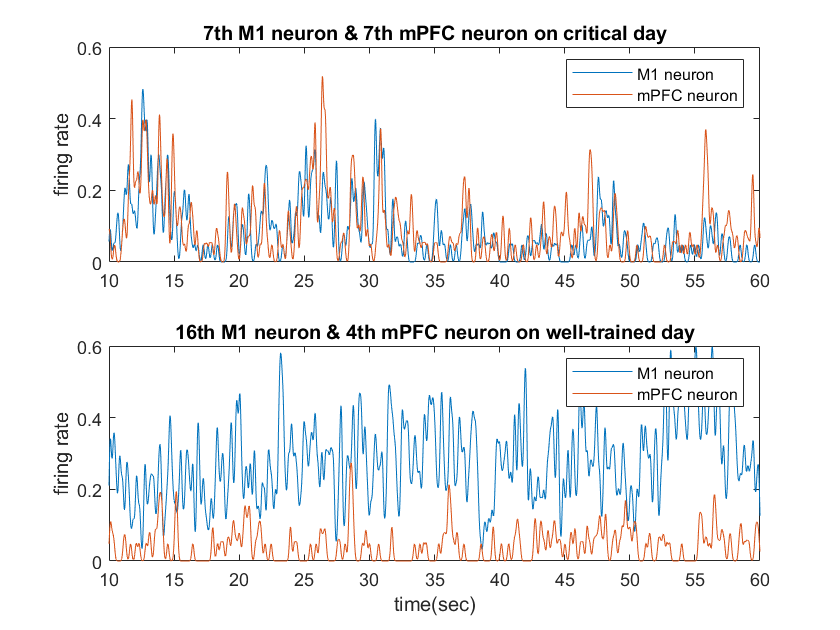

close all;clear;clc;
[M1c, mPFCc] = spikeTime2Train("data/data_rat010_0615_event");
[M1w, mPFCw] = spikeTime2Train("data/rat_010_07_04.mat");

t=10:0.01:60;
bins = 1000:6000;
figure
subplot(2,1,1)
plot(t, gaussianSmooth(M1c(bins,7), 50))
hold on
plot(t, gaussianSmooth(mPFCc(bins,7), 50))
title("7th M1 neuron & 7th mPFC neuron on critical day")
legend("M1 neuron", "mPFC neuron")
ylabel("firing rate")
subplot(2,1,2)
plot(t, gaussianSmooth(M1w(bins,16), 50))
hold on
plot(t, gaussianSmooth(mPFCw(bins,4), 50))
title("16th M1 neuron & 4th mPFC neuron on well-trained day")
legend("M1 neuron", "mPFC neuron")
xlabel("time(sec)")
ylabel("firing rate")

close all;clear;clc;
load data/data_rat010_0615_spike_train_selected_with_delay.mat
M1Idx = 1;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,1);
length(trainY)/100

ans = 137.7800